# **Projetar as funções de transferência dos filtros ativos que seguem com aproximação Butterworth:**

Deve ser apresentado  todo o equacionamento para se obter as funções de transferência a partir das funções normalizadas (polinômios de Butterworth). A partir da  função de transferência, apresentar a resposta em frequência do filtro  (magnitude e fase).  Apresentar ao menos simulações de sinais senoidais  (sobrepor sinal de entrada e saída) na banda passante, na frequência de  corte e na banda de rejeição dos filtros. Comparar os resultados obtidos na simulação com os previstos pela resposta em frequência.

clc;
clear;
K = 1;
s = tf("s");
interval = {0, 1e12};
rad_s = 2 * pi; % 1 Hz = 2 * pi rad/s

function simulate_filter_response(H, f, T)
    dt = 1e-6; 
    t = 0:dt:T; 
    u = sin(2 * pi*f*t); 
    
    [y, t_out] = lsim(H, u, t);
   
    figure;
    plot(t_out, u, 'b', t_out, y, 'r');
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend('Entrada', 'Saída');
    title(['Resposta do Filtro (f = ' num2str(f) ' Hz, Tempo Simulado = ' num2str(T) ' s)']);
    grid on;
end

**1) Passa-baixas de primeira ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 1ª Ordem");

Passa baixa 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

% polinomio normalizado de primeira ordem
butterworth_p_1 = a + 1;
H = 1 / butterworth_p_1


H =
 
    1571
  --------
  s + 1571
 
Continuous-time transfer function.
Model Properties


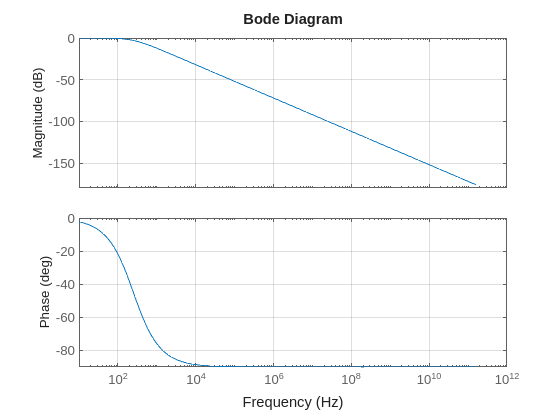


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;

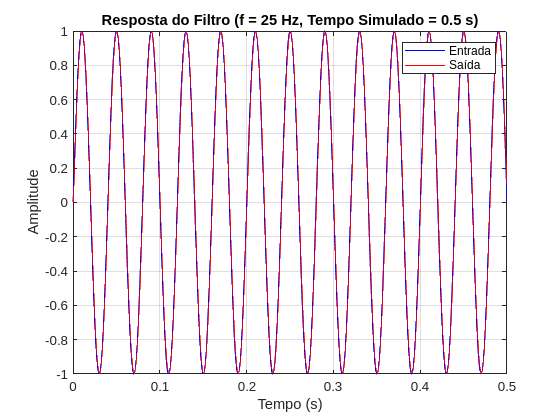


simulate_filter_response(H, Hz/10, 0.5);

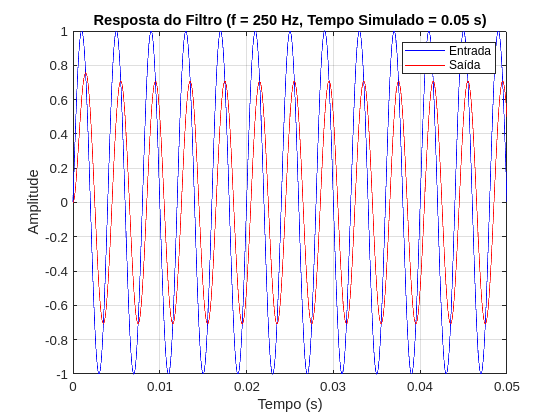

simulate_filter_response(H, Hz, 0.05);

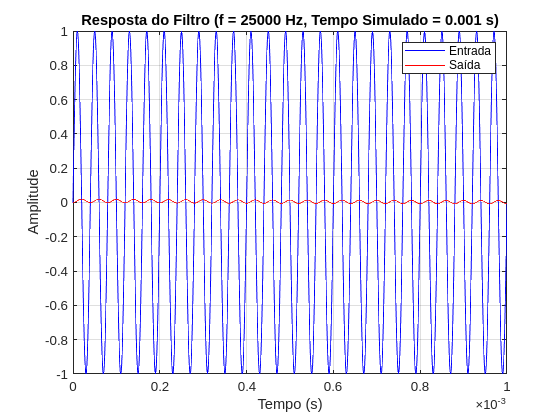

simulate_filter_response(H, Hz*100, 0.001);

**2) Passa-altas de primeira ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 1ª Ordem");

Passa alta 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);
a = 1/a; %low pass to high pass (pag 28)

% polinomio normalizado de primeira ordem 
butterworth_p_1 = a + 1;
H = 1 / butterworth_p_1


H =
 
     s
  --------
  s + 1571
 
Continuous-time transfer function.
Model Properties


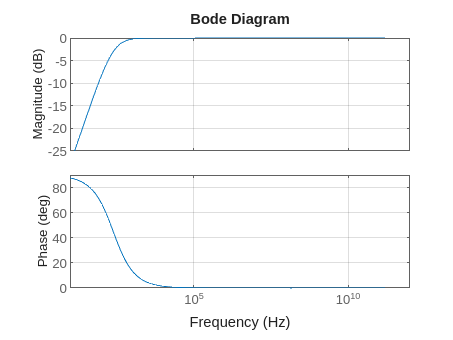


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;

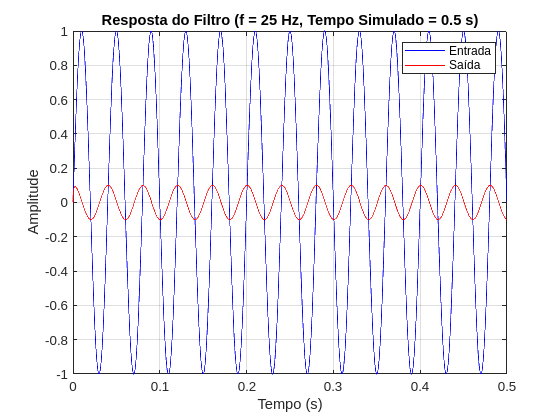


simulate_filter_response(H, Hz/10, 0.5);

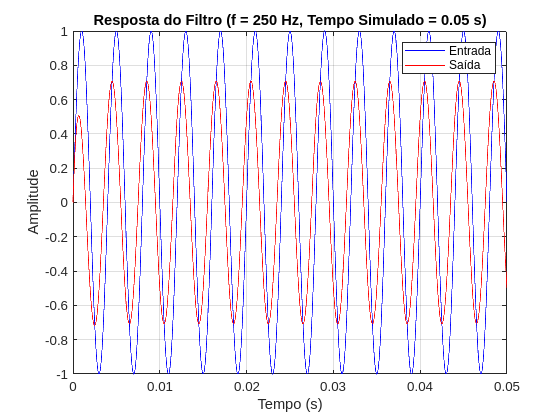

simulate_filter_response(H, Hz, 0.05);

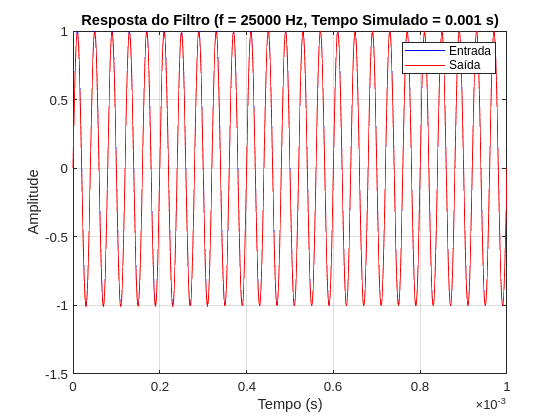

simulate_filter_response(H, Hz*100, 0.001);

**3) Passa-baixas de segunda ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 2ª Ordem");

Passa baixa 250Hz - 2ª Ordem


a = s / (Hz * rad_s);

% polinomio normalizado de segunda ordem
butterworth_p_2 = a^2 + a*1.4142 + 1;
H = 1 / butterworth_p_2


H =
 
              3.876e09
  --------------------------------
  1571 s^2 + 3.489e06 s + 3.876e09
 
Continuous-time transfer function.
Model Properties


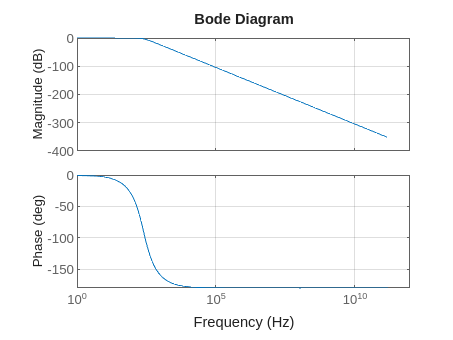


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;

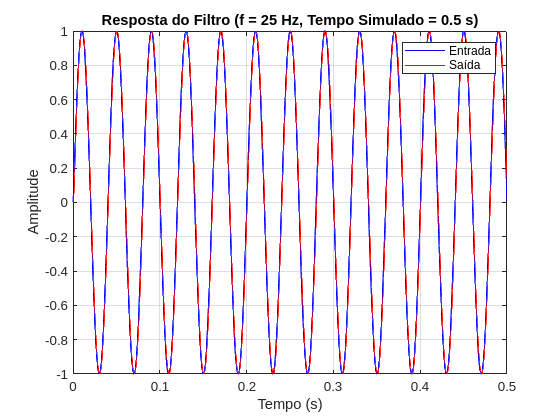


simulate_filter_response(H, Hz/10, 0.5);

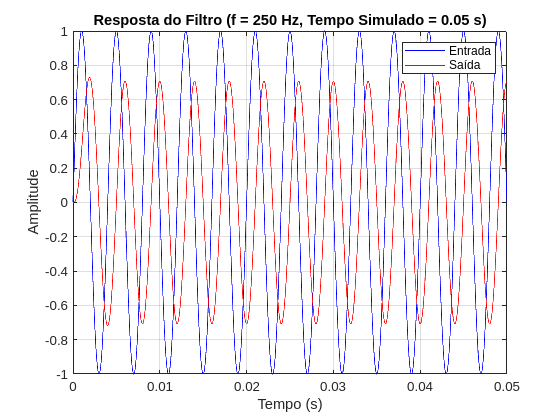

simulate_filter_response(H, Hz, 0.05);

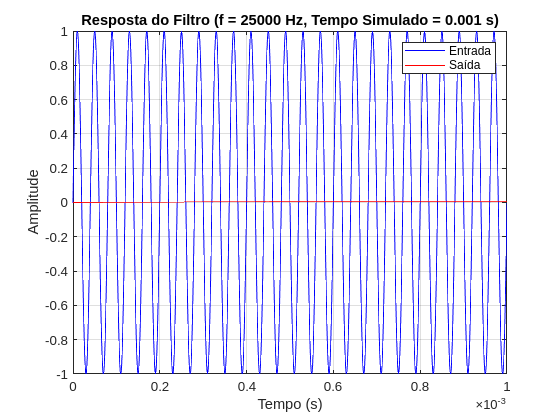

simulate_filter_response(H, Hz*100, 0.001);

**4) Passa-altas de segunda ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 2ª Ordem");

Passa alta 250Hz - 2ª Ordem


Hz = 250;
a = s / (Hz * rad_s);
a = 1 / a; %low pass to high pass (pag 28)

% polinomio normalizado de segunda ordem
butterworth_p_2 = a^2 + a*1.4142 + 1;
H = (a^2) / butterworth_p_2


H =
 
          2.467e06 s^3
  -----------------------------
  s^5 + 2221 s^4 + 2.467e06 s^3
 
Continuous-time transfer function.
Model Properties


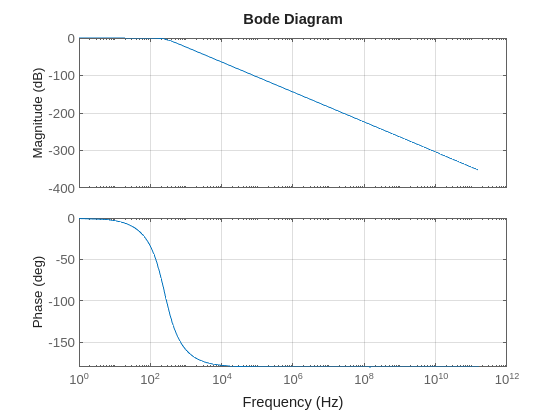


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;


simulate_filter_response(H, Hz/10, 0.5);

simulate_filter_response(H, Hz, 0.05);

simulate_filter_response(H, Hz*100, 0.001);

**5) Passa-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**

disp("Passa banda centrada em 250Hz e com Bw 1000Hz - 2ª Ordem");

Passa banda centrada em 250Hz e com Bw 1000Hz - 2ª Ordem


Hz_center = 250 * rad_s;
B = 1000 * rad_s;

% low pass to band pass (chapter 2 filtro ativo pag 30)
a = (Hz_center/B) * ((s/Hz_center) + (Hz_center/s));

% polinomio normalizado de segunda ordem
%butterworth_p_2 = a^2 + a*1.4142 + 1;
%H = 1 / butterworth_p_2
butterworth_p_1 = a + 1;
H = 1 / butterworth_p_1


H =
 
             1571 s
  ----------------------------
  0.25 s^2 + 1571 s + 6.169e05
 
Continuous-time transfer function.
Model Properties


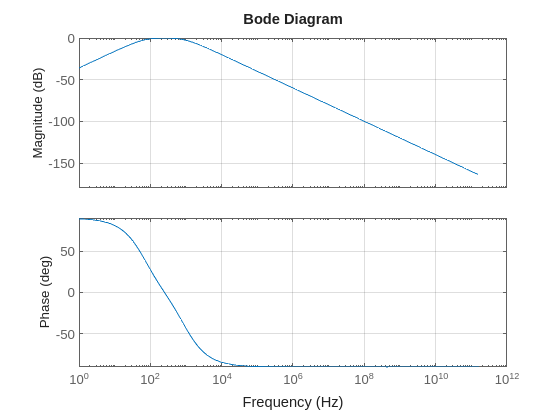


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;

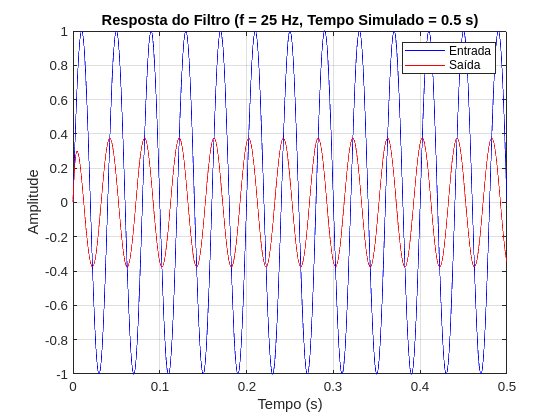


simulate_filter_response(H, Hz/10, 0.5);

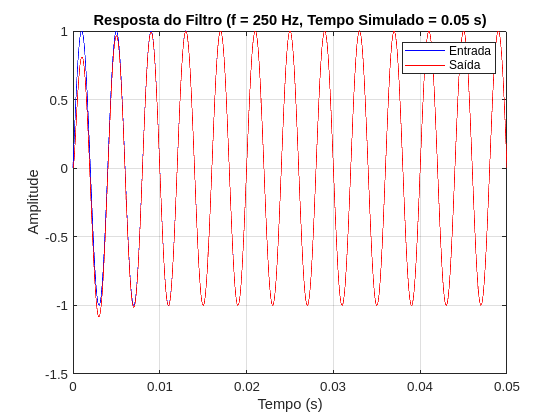

simulate_filter_response(H, Hz, 0.05);

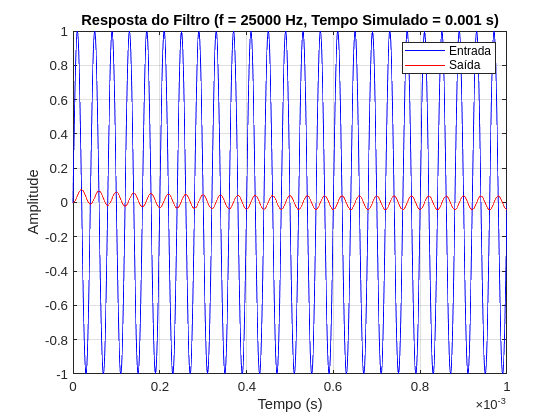

simulate_filter_response(H, Hz*100, 0.001);

**6) Rejeita-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**

disp("Rejeita banda centrada em 250Hz e com Bw 1000Hz - 2ª Ordem");

Rejeita banda centrada em 250Hz e com Bw 1000Hz - 2ª Ordem


Hz_center = 250 * rad_s;
B = 1000 * rad_s;

% low pass to band stop (chapter 2 filtro ativo pag 30)
a = B / ( Hz_center * ((s/Hz_center) + (Hz_center/s)) );

% polinomio normalizado de segunda ordem
butterworth_p_2 = a^2 + a*1.4142 + 1;
H = 1 / butterworth_p_2


H =
 
                       3.876e09 s^6 + 2.869e16 s^4 + 7.079e22 s^2 + 5.822e28
  ------------------------------------------------------------------------------------------------
  3.876e09 s^6 + 3.444e13 s^5 + 1.817e17 s^4 + 1.699e20 s^3 + 4.483e23 s^2 + 2.097e26 s + 5.822e28
 
Continuous-time transfer function.
<a href="matlab:disp(char('','       Numerator: {[3.8758e+09 0 2.8689e+16 0 7.0788e+22 0 5.8221e+28]} ','     Denominator: {[3.8758e+09 3.4439e+13 1.8170e+17 1.6995e+20 4.4832e+23 2.0967e+26 5.8221e+28]} ','        Variable: ''s'' ','         IODelay: 0 ','      InputDelay: 0 ','     OutputDelay: 0 ','       InputName: {''''} ','       InputUnit: {''''} ','      InputGroup: [1×1 struct] ','      OutputName: {''''} ','      OutputUnit: {''''} ','     OutputGroup: [1×1 struct] ','           Notes: [0×1 string] ','        UserData: [] ','            Name: '''' ','              Ts: 0 ','        TimeUnit: ''seconds'' ','    SamplingGrid: [1×1 struct] ',' '))">Model Properties</

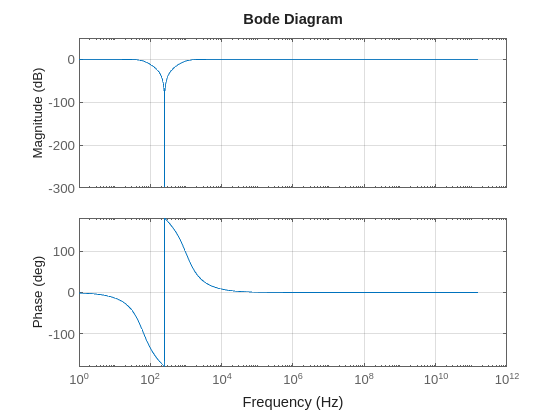


bp = bodeplot(H, interval);
bp.FrequencyUnit = "Hz";
grid on;

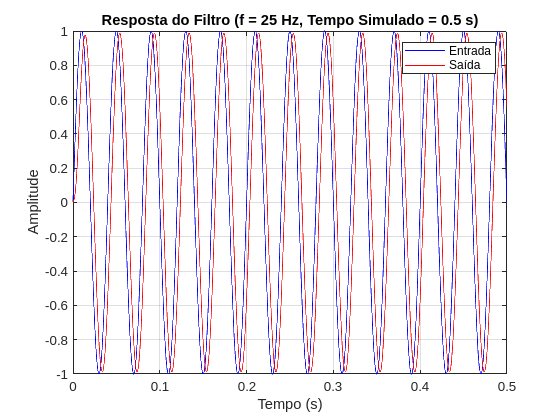


simulate_filter_response(H, Hz/10, 0.5);

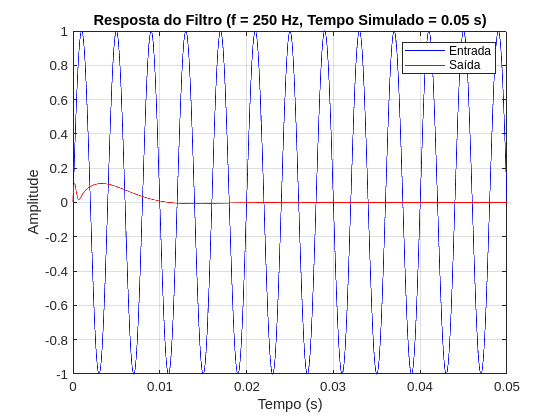

simulate_filter_response(H, Hz, 0.05);

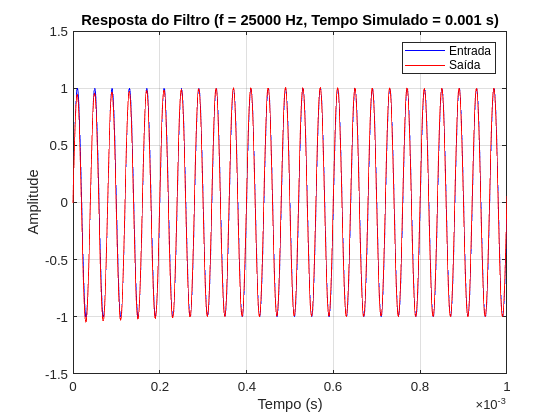

simulate_filter_response(H, Hz*100, 0.001);